# Human ECG

Note: ループで回すと実行時間が長くなるので個別に処理をする

## figureを作成

f1 = figure('Name','SAMPLE 01');
f2 = figure('Name','SAMPLE 02');
f3 = figure('Name','SAMPLE 03');
f4 = figure('Name','SAMPLE 04');
f5 = figure('Name','SAMPLE 05');
f6 = figure('Name','SAMPLE 06');
f7 = figure('Name','SAMPLE 07');
f8 = figure('Name','SAMPLE 08');
f9 = figure('Name','SAMPLE 09');
fX = figure('Name','SAMPLE 10');
fY = figure('Name','SAMPLE 01 FASTCLIP 1000S');
fZ = figure('Name','SAMPLE 01 AGPOSS 1000S');
fA = figure('Name','HUM FASTCLIP');
fB = figure('Name','HUM AGPOSS');

## linspaceを作成

xa: 全サンプル

xp: 2秒分(1000samples)のサンプル

xa = linspace(1,30000,30000);
xp = linspace(1,1000,1000);

同時samplingなのでdataをalignする必要は無い

% yfa=zeros(10, 30000);
% yaa=zeros(10, 30000);
% for hc=1:10
%     for c=1:30000
%         yfa(hc,c) = humfas(hc,c);
%         yaa(hc,c) = humagp(hc,c);
%     end
% end

% yfp=zeros(10, 1000);
% yap=zeros(10, 1000);
% b = 10000;
% for hc=1:10
%     for c=1:1000
%         yfp(hc,c) = humfas(hc, b+c);
%         yap(hc,c) = humagp(hc, b+c);
%     end
% end

## データ読み込み

`変数名のformat`

`y?NN?`

`^^ ^^`

`|| |plot type ("a"ll/"p"artial)`

`|| sample number (01-10)`

`|electrode type ("f"astclip/"a"gposs)`

`"y"-axis`

すべてのデータをy?NNaに格納

yf01a = humfas01;
ya01a = humagp01;
yf02a = humfas02;
ya02a = humagp02;
yf03a = humfas03;
ya03a = humagp03;
yf04a = humfas04;
ya04a = humagp04;
yf05a = humfas05;
ya05a = humagp05;
yf06a = humfas06;
ya06a = humagp06;
yf07a = humfas07;
ya07a = humagp07;
yf08a = humfas08;
ya08a = humagp08;
yf09a = humfas09;
ya09a = humagp09;
yf10a = humfas10;
ya10a = humagp10;

サンプリング開始20秒後を起点に1000サンプルを抽出してy?NNpに格納

cstart=10001;
cstop=11000;
yf01p = humfas01(cstart:cstop);
ya01p = humagp01(cstart:cstop);
yf02p = humfas02(cstart:cstop);
ya02p = humagp02(cstart:cstop);
yf03p = humfas03(cstart:cstop);
ya03p = humagp03(cstart:cstop);
yf04p = humfas04(cstart:cstop);
ya04p = humagp04(cstart:cstop);
yf05p = humfas05(cstart:cstop);
ya05p = humagp05(cstart:cstop);
yf06p = humfas06(cstart:cstop);
ya06p = humagp06(cstart:cstop);
yf07p = humfas07(cstart:cstop);
ya07p = humagp07(cstart:cstop);
yf08p = humfas08(cstart:cstop);
ya08p = humagp08(cstart:cstop);
yf09p = humfas09(cstart:cstop);
ya09p = humagp09(cstart:cstop);
yf10p = humfas10(cstart:cstop);
ya10p = humagp10(cstart:cstop);

#### レベルの違いを吸収するために正規化

y?NNaを正規化

% yf01a = normalize(yf01a);
% ya01a = normalize(ya01a);
% yf02a = normalize(yf02a);
% ya02a = normalize(ya02a);
% yf03a = normalize(yf03a);
% ya03a = normalize(ya03a);
% yf04a = normalize(yf04a);
% ya04a = normalize(ya04a);
% yf05a = normalize(yf05a);
% ya05a = normalize(ya05a);
% yf06a = normalize(yf06a);
% ya06a = normalize(ya06a);
% yf07a = normalize(yf07a);
% ya07a = normalize(ya07a);
% yf08a = normalize(yf08a);
% ya08a = normalize(ya08a);
% yf09a = normalize(yf09a);
% ya09a = normalize(ya09a);
% yf10a = normalize(yf10a);
% ya10a = normalize(ya10a);

y?NNpを正規化

% yf01p = normalize(yf01p);
% ya01p = normalize(ya01p);
% yf02p = normalize(yf02p);
% ya02p = normalize(ya02p);
% yf03p = normalize(yf03p);
% ya03p = normalize(ya03p);
% yf04p = normalize(yf04p);
% ya04p = normalize(ya04p);
% yf05p = normalize(yf05p);
% ya05p = normalize(ya05p);
% yf06p = normalize(yf06p);
% ya06p = normalize(ya06p);
% yf07p = normalize(yf07p);
% ya07p = normalize(ya07p);
% yf08p = normalize(yf08p);
% ya08p = normalize(ya08p);
% yf09p = normalize(yf09p);
% ya09p = normalize(ya09p);
% yf10p = normalize(yf10p);
% ya10p = normalize(ya10p);

#### plot

y?NNaのcombined plot

% for c=1:10
%     figure(f1);
%     plot(xa, yfa(c), xa, yaa(c))
%     legend("FASTCLIP", "AGPOSS");
%     xlabel("SAMPLE COUNT");
%     ylabel("NORMALISED VALUE");
%     texttitle = "SAMPLE " + c + " ALL";
%     title(texttitle);
% end

% figure(fY);
% plot(xa, yf01a, xa, ya01a)
% xtickformat('%6d')
% legend("FASTCLIP", "AGPOSS");
% xlabel("SAMPLE COUNT");
% ylabel("VALUE");
% figure(f1);

plot(xa, yf01a, '--', xa, ya01a, ':', LineWidth=2)
ylim([150 550])
%xtickformat('%6d')
legend("Fastclip electrodes", "Silver fiber electrodes");
xlabel("Sample count (times)");
ylabel("Value");
fontname("Bahnschrift");
fontsize(60,'points');
title("Sample 1 (all, combined plot)");

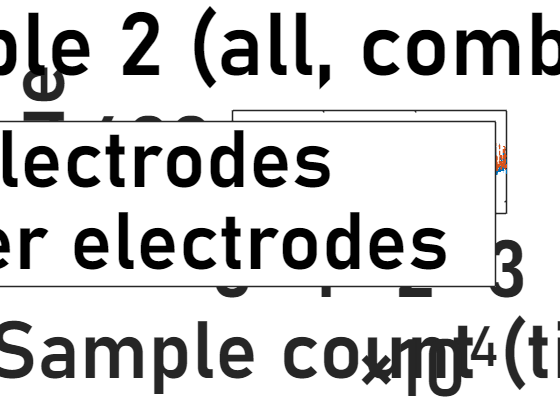

figure(f2);
plot(xa, yf02a, '--', xa, ya02a, ':', LineWidth=2)
ylim([150 550])
legend("Fastclip electrodes", "Silver fiber electrodes");
xlabel("Sample count (times)");
ylabel("Value");
fontname("Bahnschrift");
fontsize(60,'points');
title("Sample 2 (all, combined plot)");

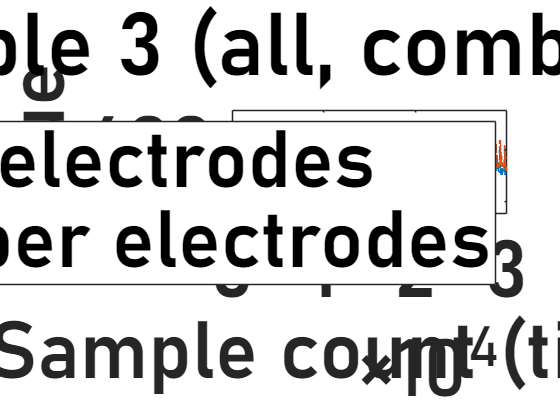

figure(f3);
plot(xa, yf03a, '--', xa, ya03a, ':', LineWidth=2)
ylim([150 550])
legend("Fastclip electrodes", "Silver fiber electrodes");
xlabel("Sample count (times)");
ylabel("Value");
fontname("Bahnschrift");
fontsize(60,'points');
title("Sample 3 (all, combined plot)");

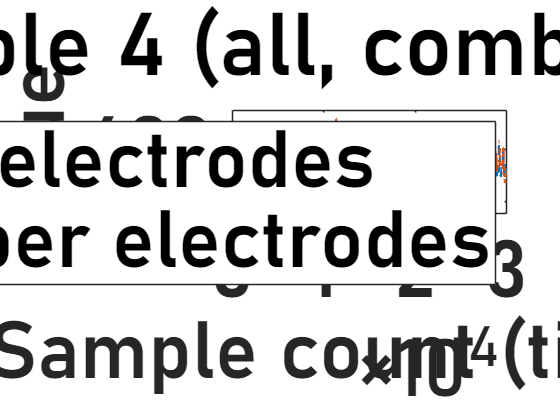

figure(f4);
plot(xa, yf04a, '--', xa, ya04a, ':', LineWidth=2)
ylim([150 550])
legend("Fastclip electrodes", "Silver fiber electrodes");
xlabel("Sample count (times)");
ylabel("Value");
fontname("Bahnschrift");
fontsize(60,'points');
title("Sample 4 (all, combined plot)");

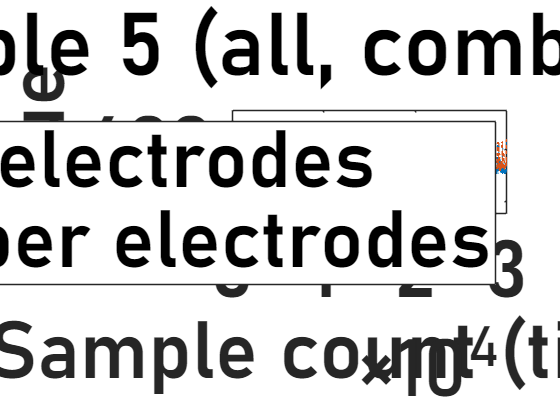

figure(f5);
plot(xa, yf05a, '--', xa, ya05a, ':', LineWidth=2)
ylim([150 550])
legend("Fastclip electrodes", "Silver fiber electrodes");
xlabel("Sample count (times)");
ylabel("Value");
fontname("Bahnschrift");
fontsize(60,'points');
title("Sample 5 (all, combined plot)");

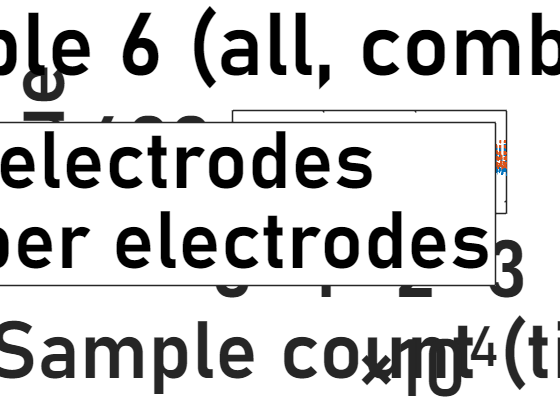

figure(f6);
plot(xa, yf06a, '--', xa, ya06a, ':', LineWidth=2)
ylim([150 550])
legend("Fastclip electrodes", "Silver fiber electrodes");
xlabel("Sample count (times)");
ylabel("Value");
fontname("Bahnschrift");
fontsize(60,'points');
title("Sample 6 (all, combined plot)");

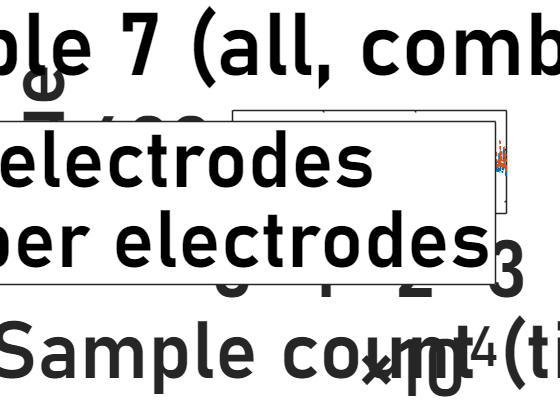

figure(f7);
plot(xa, yf07a, '--', xa, ya07a, ':', LineWidth=2)
ylim([150 550])
legend("Fastclip electrodes", "Silver fiber electrodes");
xlabel("Sample count (times)");
ylabel("Value");
fontname("Bahnschrift");
fontsize(60,'points');
title("Sample 7 (all, combined plot)");

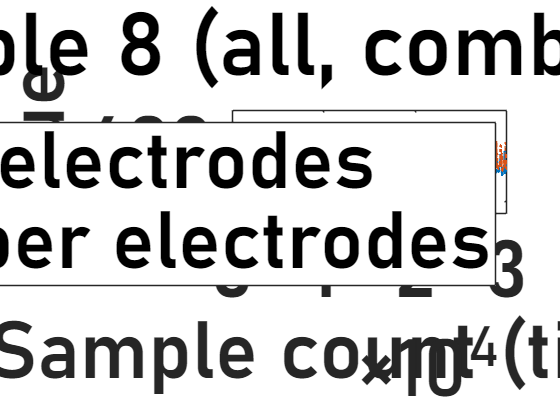

figure(f8);
plot(xa, yf08a, '--', xa, ya08a, ':', LineWidth=2)
ylim([150 550])
legend("Fastclip electrodes", "Silver fiber electrodes");
xlabel("Sample count (times)");
ylabel("Value");
fontname("Bahnschrift");
fontsize(60,'points');
title("Sample 8 (all, combined plot)");

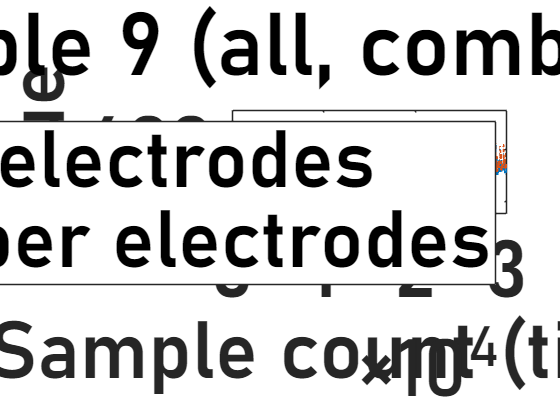

figure(f9);
plot(xa, yf09a, '--', xa, ya09a, ':', LineWidth=2)
ylim([150 550])
legend("Fastclip electrodes", "Silver fiber electrodes");
xlabel("Sample count (times)");
ylabel("Value");
fontname("Bahnschrift");
fontsize(60,'points');
title("Sample 9 (all, combined plot)");

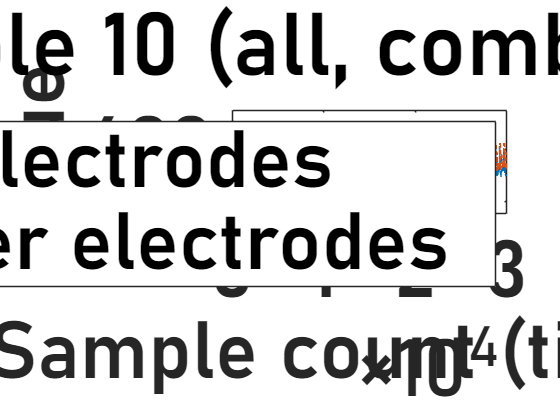

figure(fX);
plot(xa, yf10a, '--', xa, ya10a, ':', LineWidth=2)
ylim([150 550])
legend("Fastclip electrodes", "Silver fiber electrodes");
xlabel("Sample count (times)");
ylabel("Value");
fontname("Bahnschrift");
fontsize(60,'points');
title("Sample 10 (all, combined plot)");

#### y?NNpのcombined plot

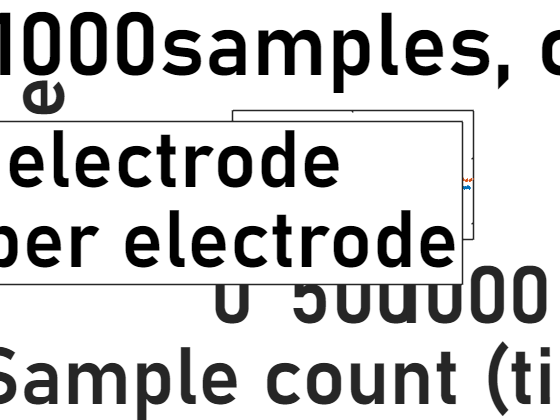

% figure(f1);
% plot(xp, yf01p, '--', xp, ya01p, ':', LineWidth=4)
% ylim([250 550])
% legend("Fastclip electrode", "Silver fiber electrode");
% xlabel("Sample count (times)");
% ylabel("Value");
% fontname("Bahnschrift");
% fontsize(60,'points');
% figure(fA);
% plot(xp, yf01p, LineWidth=4, Color=[0 0.2 0.2])
% ylim([250 550])
% xlabel("Sample count (times)");
% ylabel("Value");
% fontname("Bahnschrift");
% fontsize(60,'points');
% figure(fB);
% plot(xp, ya01p, LineWidth=4, Color=[0 0.2 0.2])
% ylim([250 550])
% xlabel("Sample count (times)");
% ylabel("Value");
% fontname("Bahnschrift");
% fontsize(60,'points');
% 
% title("SAMPLE 01 PARTIAL");
% figure(f2);
% plot(xp, yf02p, xp, ya02p)
% legend("FASTCLIP", "AGPOSS");
% xlabel("SAMPLE COUNT");
% ylabel("NORMALISED VALUE");
% 
% title("SAMPLE 02 PARTIAL");
% figure(f3);
% plot(xp, yf03p, xp, ya03p)
% legend("FASTCLIP", "AGPOSS");
% xlabel("SAMPLE COUNT");
% ylabel("NORMALISED VALUE");
% title("SAMPLE 03 PARTIAL");

plot(xp, yf01p, '--', xp, ya01p, ':', LineWidth=2)
ylim([150 550])
legend("Fastclip electrode", "Silver fiber electrode");
xlabel("Sample count (times)");
ylabel("Value");
fontname("Bahnschrift");
fontsize(60,'points');
title("Sample 1 (1000samples, combined plot)");

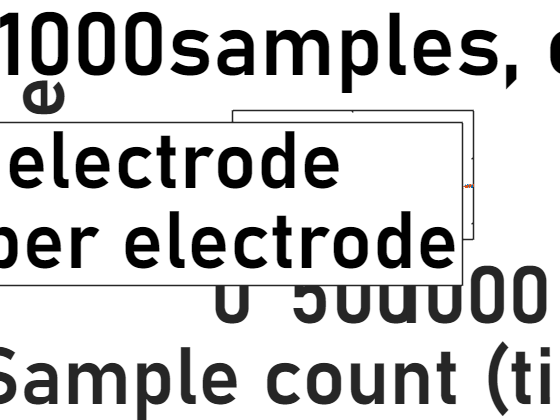


plot(xp, yf02p, '--', xp, ya02p, ':', LineWidth=2)
ylim([150 550])
legend("Fastclip electrodes", "Silver fiber electrodes");
xlabel("Sample count (times)");
ylabel("Value");
fontname("Bahnschrift");
fontsize(60,'points');
title("Sample 2 (1000samples, combined plot)");

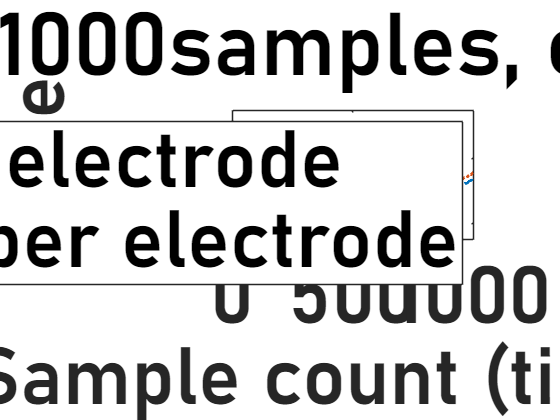


plot(xp, yf03p, '--', xp, ya03p, ':', LineWidth=2)
ylim([150 550])
legend("Fastclip electrodes", "Silver fiber electrodes");
xlabel("Sample count (times)");
ylabel("Value");
fontname("Bahnschrift");
fontsize(60,'points');
title("Sample 3 (1000samples, combined plot)");

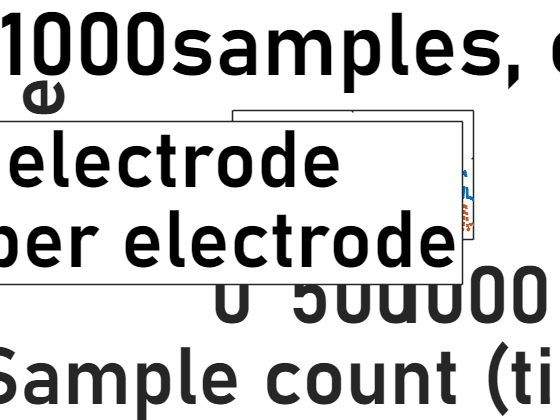

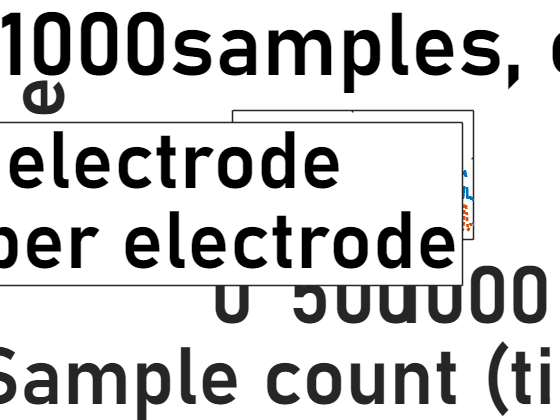


plot(xp, yf04p, '--', xp, ya04p, ':', LineWidth=2)
ylim([150 550])
legend("Fastclip electrodes", "Silver fiber electrodes");
xlabel("Sample count (times)");
ylabel("Value");
fontname("Bahnschrift");
fontsize(60,'points');
title("Sample 4 (1000samples, combined plot)");

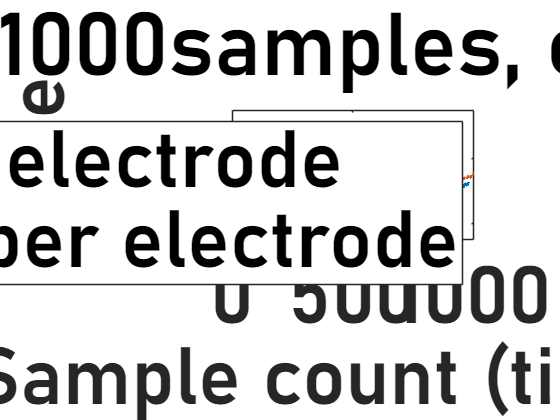


plot(xp, yf05p, '--', xp, ya05p, ':', LineWidth=2)
ylim([150 550])
legend("Fastclip electrodes", "Silver fiber electrodes");
xlabel("Sample count (times)");
ylabel("Value");
fontname("Bahnschrift");
fontsize(60,'points');
title("Sample 5 (1000samples, combined plot)");

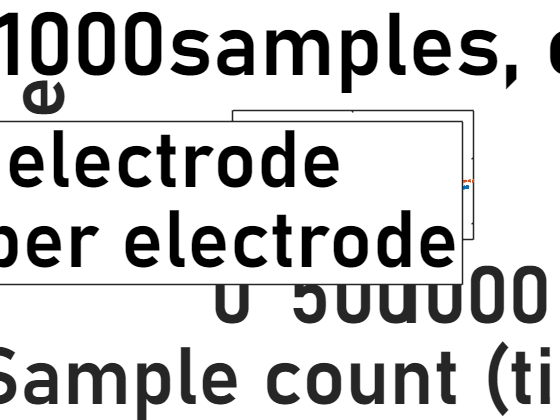


figure(f6);
plot(xp, yf06p, '--', xp, ya06p, ':', LineWidth=2)
ylim([150 550])
legend("Fastclip electrodes", "Silver fiber electrodes");
xlabel("Sample count (times)");
ylabel("Value");
fontname("Bahnschrift");
fontsize(60,'points');
title("Sample 6 (1000samples, combined plot)");

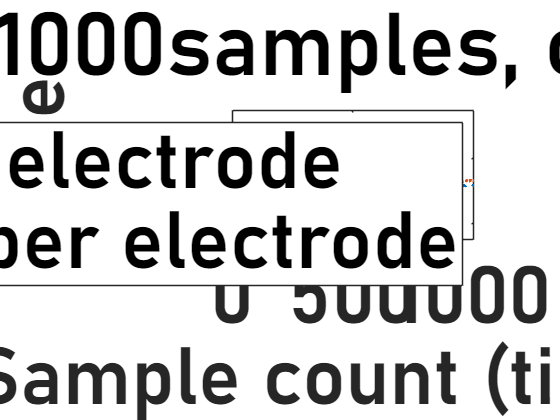


figure(f7);
plot(xp, yf07p, '--', xp, ya07p, ':', LineWidth=2)
ylim([150 550])
legend("Fastclip electrodes", "Silver fiber electrodes");
xlabel("Sample count (times)");
ylabel("Value");
fontname("Bahnschrift");
fontsize(60,'points');
title("Sample 7 (1000samples, combined plot)");

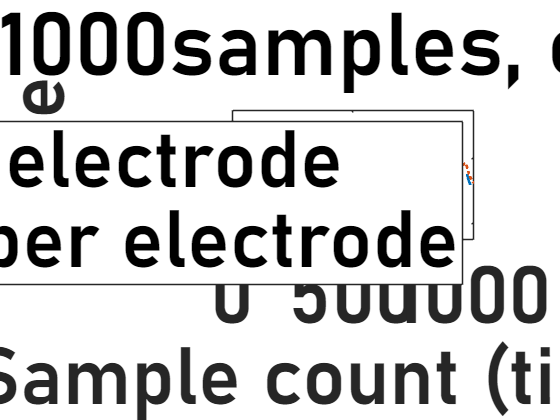


figure(f8);
plot(xp, yf08p, '--', xp, ya08p, ':', LineWidth=2)
ylim([150 550])
legend("Fastclip electrodes", "Silver fiber electrodes");
xlabel("Sample count (times)");
ylabel("Value");
fontname("Bahnschrift");
fontsize(60,'points');
title("Sample 8 (1000samples, combined plot)");

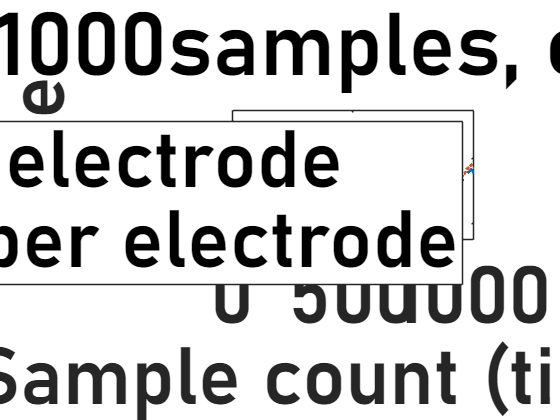


figure(f9);
plot(xp, yf09p, '--', xp, ya09p, ':', LineWidth=2)
ylim([150 550])
legend("Fastclip electrodes", "Silver fiber electrodes");
xlabel("Sample count (times)");
ylabel("Value");
fontname("Bahnschrift");
fontsize(60,'points');
title("Sample 9 (1000samples, combined plot)");

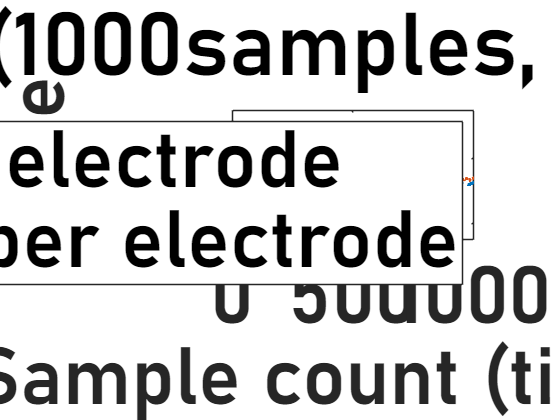


figure(fX);
plot(xp, yf10p, '--', xp, ya10p, ':', LineWidth=2)
ylim([150 550])
legend("Fastclip electrodes", "Silver fiber electrodes");
xlabel("Sample count (times)");
ylabel("Value");
fontname("Bahnschrift");
fontsize(60,'points');
title("Sample 10 (1000samples, combined plot)");

## **correlation coefficientsを計算**

**y?NNa**

% for c=1:10
% cor_a(c) = corrcoef(yfa(c),yaa(c))
% end

1

cor01a = corrcoef(yf02a,ya02a);
cor01a = cor01a(1,2)

cor01a = 0.7634

2

cor02a = corrcoef(yf02a,ya02a);
cor02a = cor02a(1,2)

cor02a = 0.7634

3

cor03a = corrcoef(yf03a,ya03a);
cor03a = cor03a(1,2)

cor03a = 0.8433

4

cor04a = corrcoef(yf04a,ya04a);
cor04a = cor04a(1,2)

cor04a = 0.7317

5

cor05a = corrcoef(yf05a,ya05a);
cor05a = cor05a(1,2)

cor05a = 0.8550

6

cor06a = corrcoef(yf06a,ya06a);
cor06a = cor06a(1,2)

cor06a = 0.8366

7

cor07a = corrcoef(yf07a,ya07a);
cor07a = cor07a(1,2)

cor07a = 0.8940

8

cor08a = corrcoef(yf08a,ya08a);
cor08a = cor08a(1,2)

cor08a = 0.9650

9

cor09a = corrcoef(yf09a,ya09a);
cor09a = cor09a(1,2)

cor09a = 0.9583

10

cor10a = corrcoef(yf10a,ya10a);
cor10a = cor10a(1,2)

cor10a = 0.7847

corava = (cor01a+cor02a+cor03a+cor04a+cor05a+cor06a+cor07a+cor08a+cor09a+cor10a)/10

corava = 0.8395

**y?NNp**

1

cor01p = corrcoef(yf01p,ya01p);
cor01p = cor01p(1,2)

cor01p = 0.9476

2

cor02p = corrcoef(yf02p,ya02p);
cor02p = cor02p(1,2)

cor02p = 0.4373

3

cor03p = corrcoef(yf03p,ya03p);
cor03p = cor03p(1,2)

cor03p = 0.9742

4

cor04p = corrcoef(yf04p,ya04p);
cor04p = cor04p(1,2)

cor04p = 0.8292

5

cor05p = corrcoef(yf05p,ya05p);
cor05p = cor05p(1,2)

cor05p = 0.9787

6

cor06p = corrcoef(yf06p,ya06p);
cor06p = cor06p(1,2)

cor06p = 0.9891

7

cor07p = corrcoef(yf07p,ya07p);
cor07p = cor07p(1,2)

cor07p = 0.9915

8

cor08p = corrcoef(yf08p,ya08p);
cor08p = cor08p(1,2)

cor08p = 0.9928

9

cor09p = corrcoef(yf09p,ya09p);
cor09p = cor09p(1,2)

cor09p = 0.9890

10

cor10p = corrcoef(yf10p,ya10p);
cor10p = cor10p(1,2)

cor10p = 0.9776

average

coravp = (cor01p+cor02p+cor03p+cor04p+cor05p+cor06p+cor07p+cor08p+cor09p+cor10p)/10

coravp = 0.9107